# Exercise 2

## Smarter Sampling

### About This Exercise

If we could sample to infinity, we could cover the entire space, but our graph would be unweildly. Can we be smarter about which samples to accept and which ones to reject so that we cover the space with fewer nodes? One such method is the visibility-based PRM, where with each new sample we choose wether to keep it dependent on what it can and cannot see and connect to.

The goal of this exercise is create a visibility-based PRM function that takes inputs of the number of nodes, the obstacles, and the limits of the space and returns a graph based on the visibility-based PRM algorithm.

**By the end of this exercise, you'll be able to: **

- **Create a probabalistic roadmap using the visibility-based PRM algorithm.**

### Visibility-Based PRM

Again, we need to set up the coordinate of the obstacles. These obstacles make up a room with two entrances with an object in the middle, which may be more challenging for a PRM to become fully connected using the methods from the previous exercise.

lim = 4;
p1x = [-.5  -2 -2 -.5 -.5 -1.5 -1.5 -.5];
p1y = [-2.5 -2.5 2.5 2.5 2 2 -2 -2];
p2x = -1.*p1x;
p2y = p1y;
p3x = [-1 -1 1 1]./2;
p3y = [-1 1 1 -1]./2;

obstacle(1).px = p1x;
obstacle(1).py = p1y;
obstacle(2).px = p2x;
obstacle(2).py = p2y;
obstacle(3).px = p3x;
obstacle(3).py = p3y;

The visibility-based PRM is quite a bit more complicated than the PRM developed in the previous exercise as we are both sampling and building the graph as we go according the the visibility rules. [CLICK HERE](matlab:open('./visibilityPRM.mlx')) to finish the function visibilityPRM. Once finished, the code below will test and plot your function.

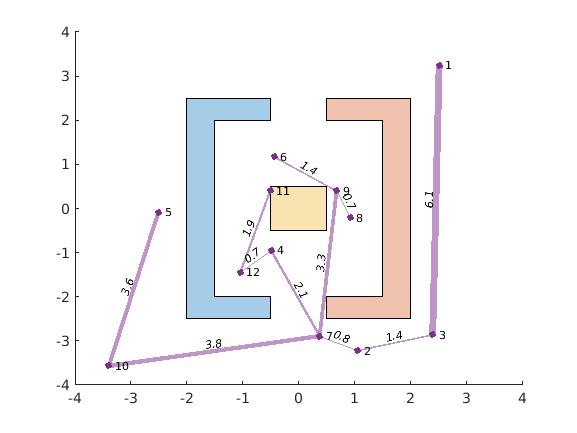

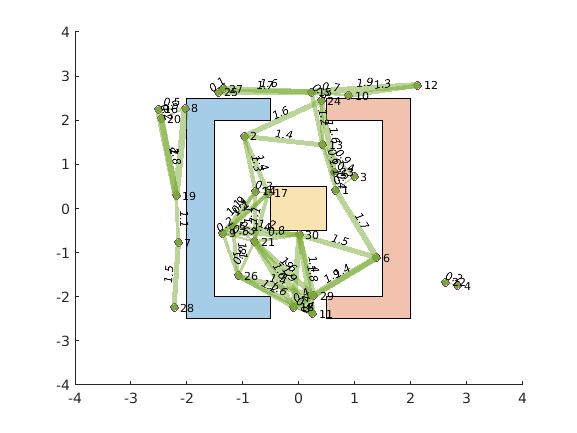

clf
M = 20;

polyvec = makePolyvec(obstacle);
[nodes_xy,A,G] = visibilityPRM(M,polyvec,lim);
plot(polyvec)
axis([-lim lim -lim lim])
hold on
LWidths = 5*G.Edges.Weight/max(G.Edges.Weight);
plot(G,'XData',nodes_xy(1,:),'YData',nodes_xy(2,:),'EdgeLabel',str2num(num2str(G.Edges.Weight,'%.1f')),'LineWidth',LWidths)

Just like before, we can use the graph search algorithm to find the shortest path on these graphs.

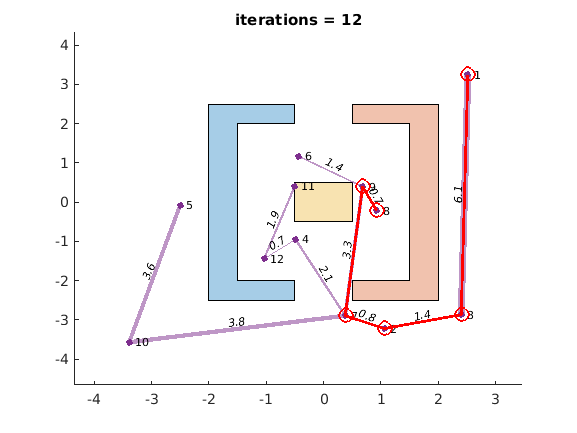

S = 8;
D = 1;
figure
plot(polyvec)
hold on
plot(G,'XData',nodes_xy(1,:),'YData',nodes_xy(2,:),'EdgeLabel',str2num(num2str(G.Edges.Weight,'%.1f')),'LineWidth',LWidths)
[path,iterations] = graphSearch(A, S, D); % Try using H as the fourth argument
plot(nodes_xy(1,path),nodes_xy(2,path),'r-o','Markersize',10,'LineWidth',2)
title(['iterations = ' num2str(iterations)])

### Finished!

While it may take more time, this version of a probabalistic roadmap will produce better coverage with fewer nodes. One obvious limitation is that this method does not produce any loops, thus there is a chance that two nodes that are close are not directly connected. It may be useful to further expand the connectivity of the graph using either the KNN or similar approach. Also, you may want to limit the extent of what  you call a connected component, so that branches far apart are considered to be in different components. 

In the final two exercises, you will explore a different probabilistic method for motion planning, where instead of creating a roadmap, you'll create a new, random tree that finds a path directly from whatever start position to any goal position while avoiding obstacles